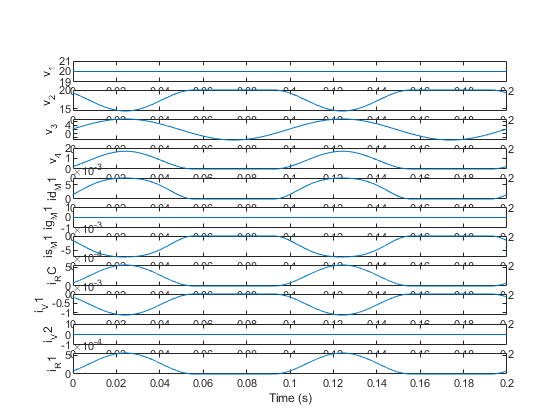

close all;

%File is a tab-delimited table of simulation results
%Row 1 contains headers
%Column 1 contains time values
%Generate an example in LTspice by running a simulation
% and choosing File -> Export data as text

cd ../Desktop/

%Input file name
datafile = "out.csv";

%Get simulation data.
simfile = importdata(datafile, ",", 1);
simdata = simfile.data;

%Loop over columns of data and plot everything on same graph
figure;
for n = 2:(size(simdata,2))
    subplot(size(simdata,2),1,n);   %Add a set of axes
    plot(simdata(:,1),simdata(:,n)); %Add the data
    ylabel(simfile.colheaders(n));  %Label the Y axis with the column header
end
xlabel('Time (s)'); %Label the x axis of the bottom plot

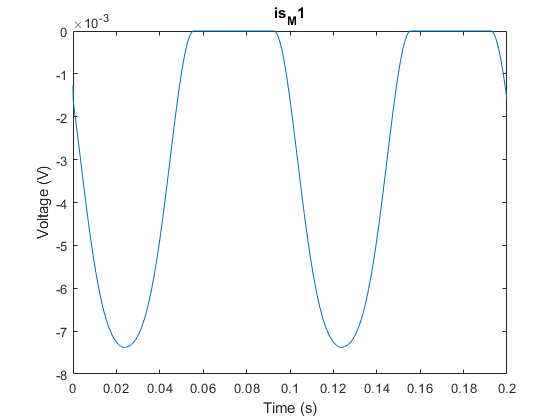



%Plot specific data on an extra graph to see more detail
specificHeader = "v_2"; %please change
headerAxisName = "Voltage (V)"; %please change

figure Name specificHeader;
for n = 2:(size(simdata, 2))
    if simfile.colheaders(n) == specificHeader
         plot(simdata(:,1),simdata(:,n)); %Add the data
         title(simfile.colheaders(n))
         ylabel(headerAxisName);  %Label the Y axis with the column header
         xlabel('Time (s)'); %Label the x axis of the bottom plot
         break;
    end
end